# LAB2 Edge detection and Hough transform

## 1 Difference operators

Question 1 

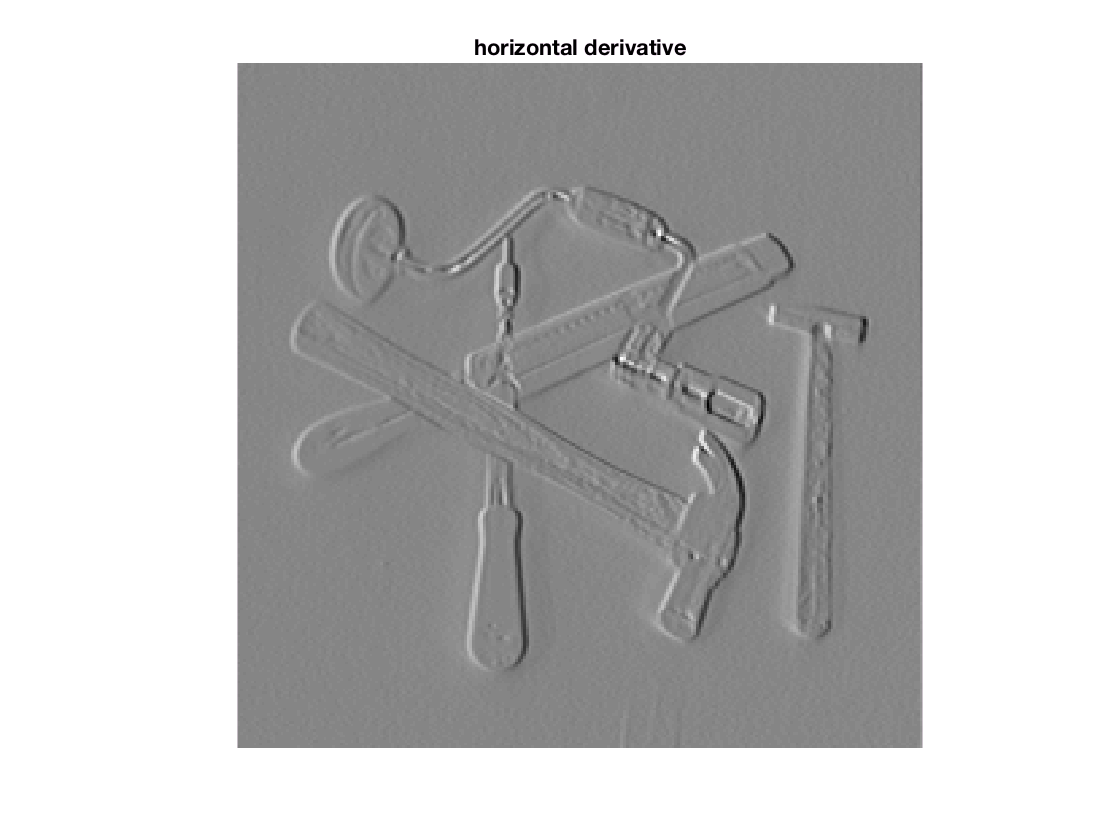

tools = few256;

deltay = [0 0 0; -0.5 0 0.5 ; 0 0 0];  %-------------simple difference operator
deltax = [0 -0.5 0 ; 0 0 0 ; 0 0.5 0 ];

dxtools = conv2(tools, deltax, 'valid');
dytools = conv2(tools, deltay, 'valid');

showgrey(dytools);
title('horizontal derivative');

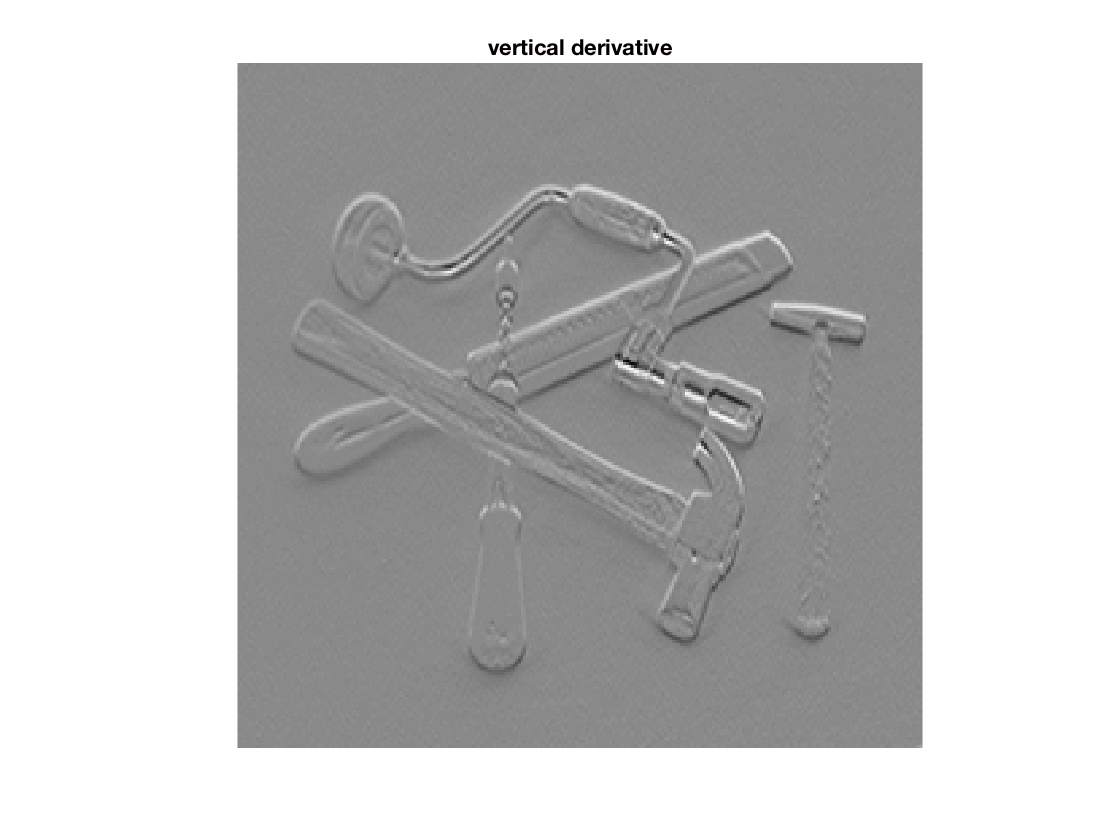

showgrey(dxtools);
title('vertical derivative');

## 2 Point-wise thresholding of gradient magnitude

Question 2 and 3

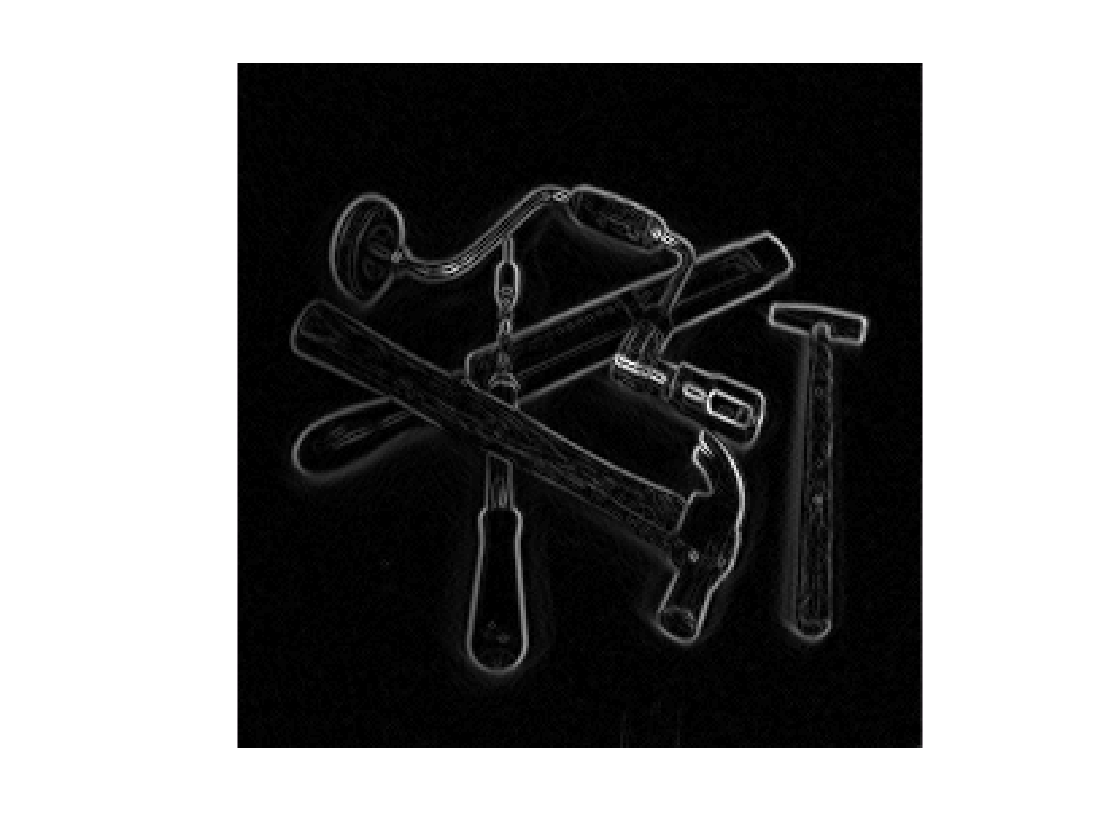

gradmagntools = sqrt(dxtools.^2 + dytools.^2);
showgrey(gradmagntools);

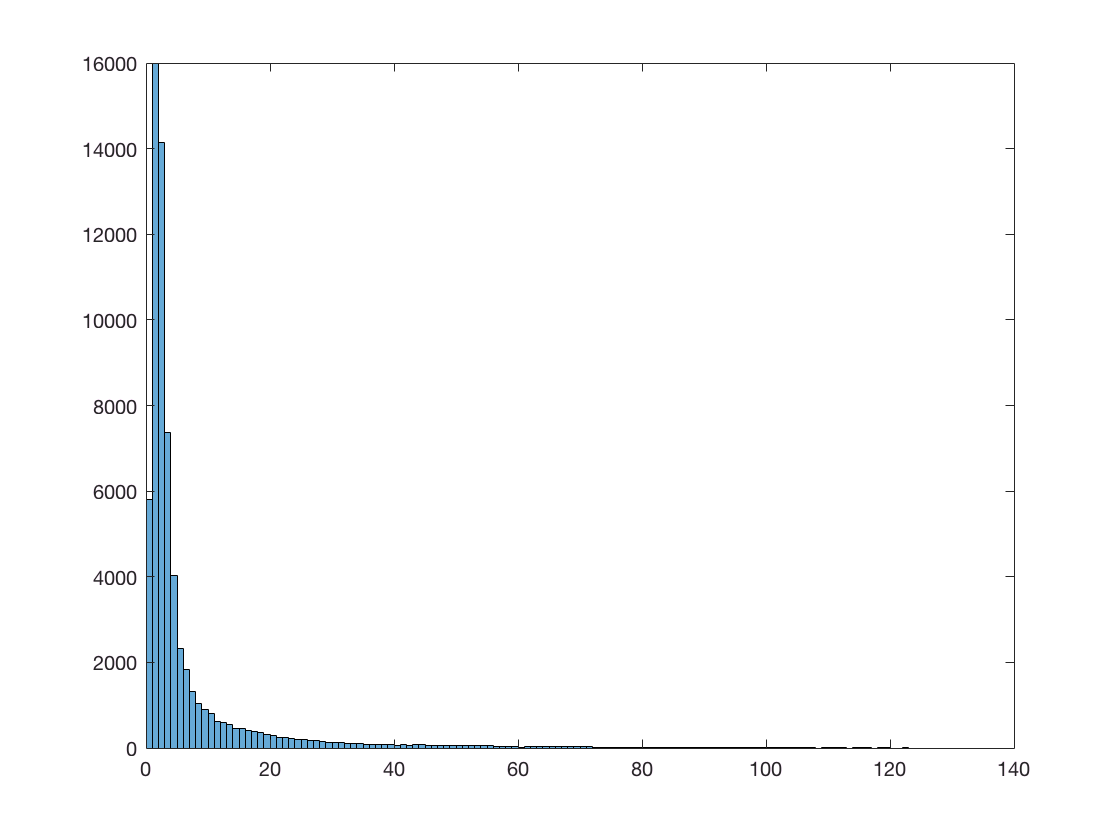

histogram(gradmagntools(:));

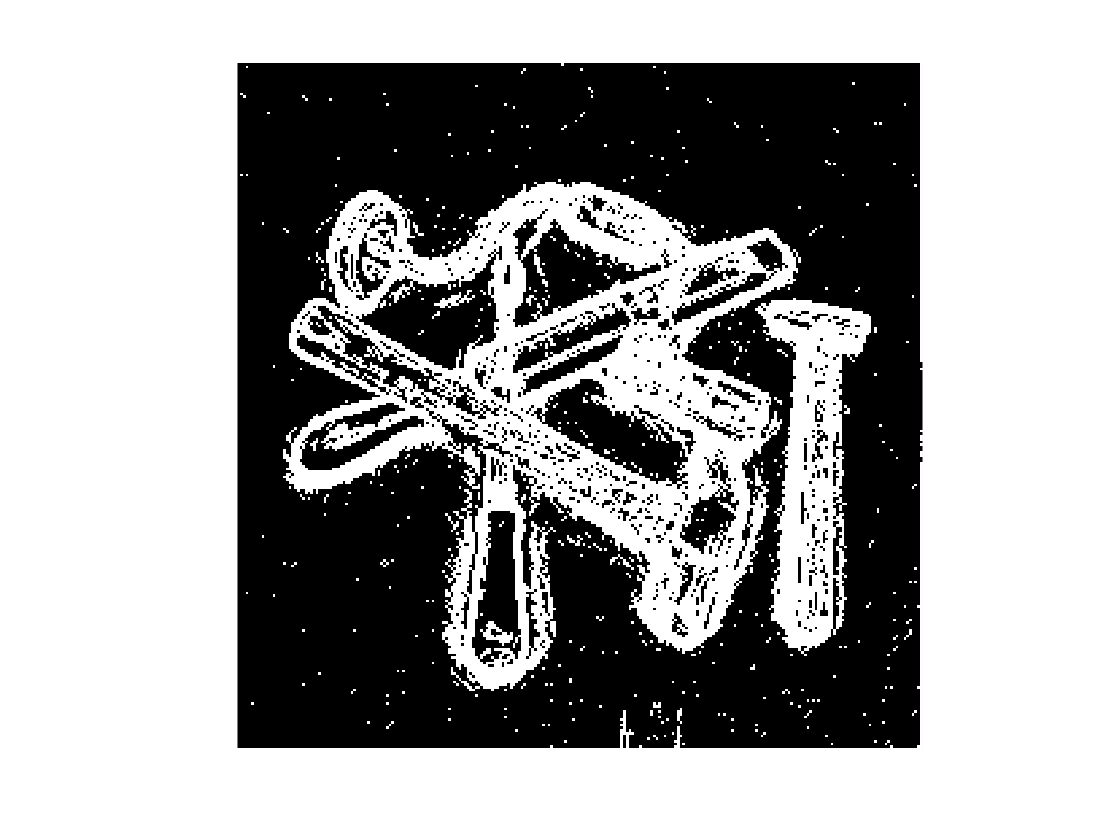

threshold = 5;
showgrey((gradmagntools-threshold)>0);

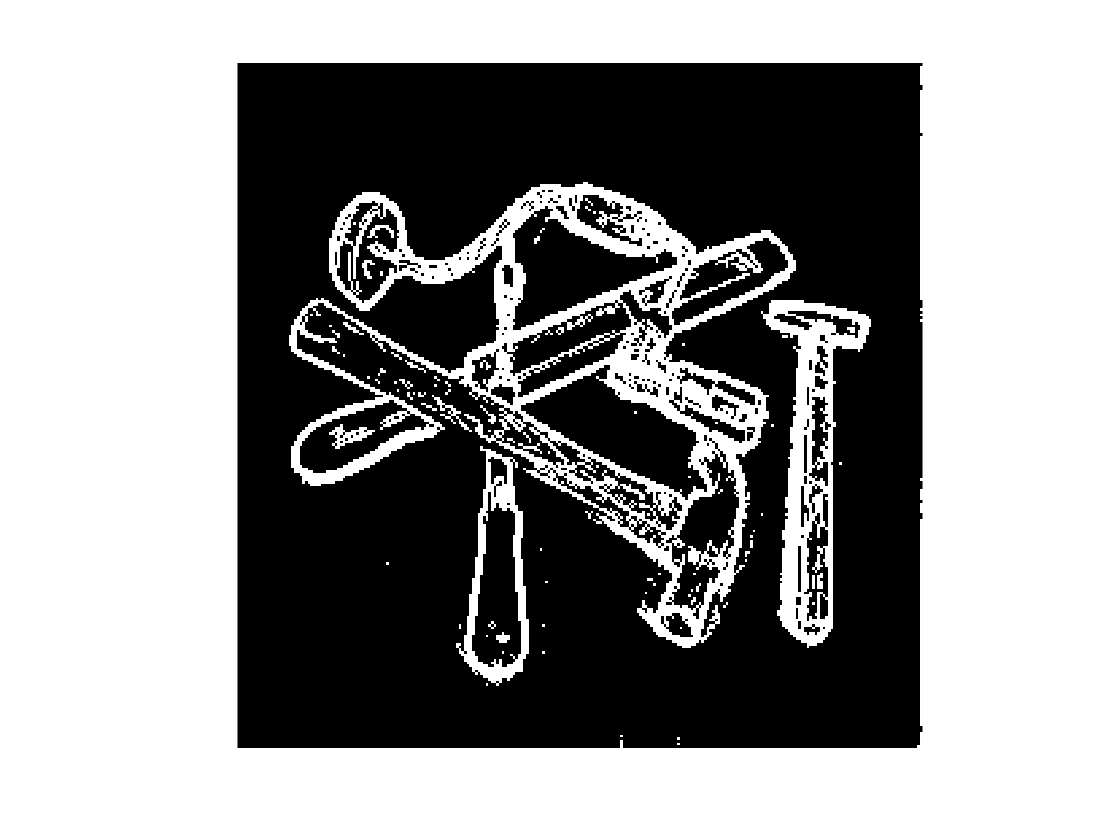

threshold = 10;
showgrey((gradmagntools-threshold)>0);

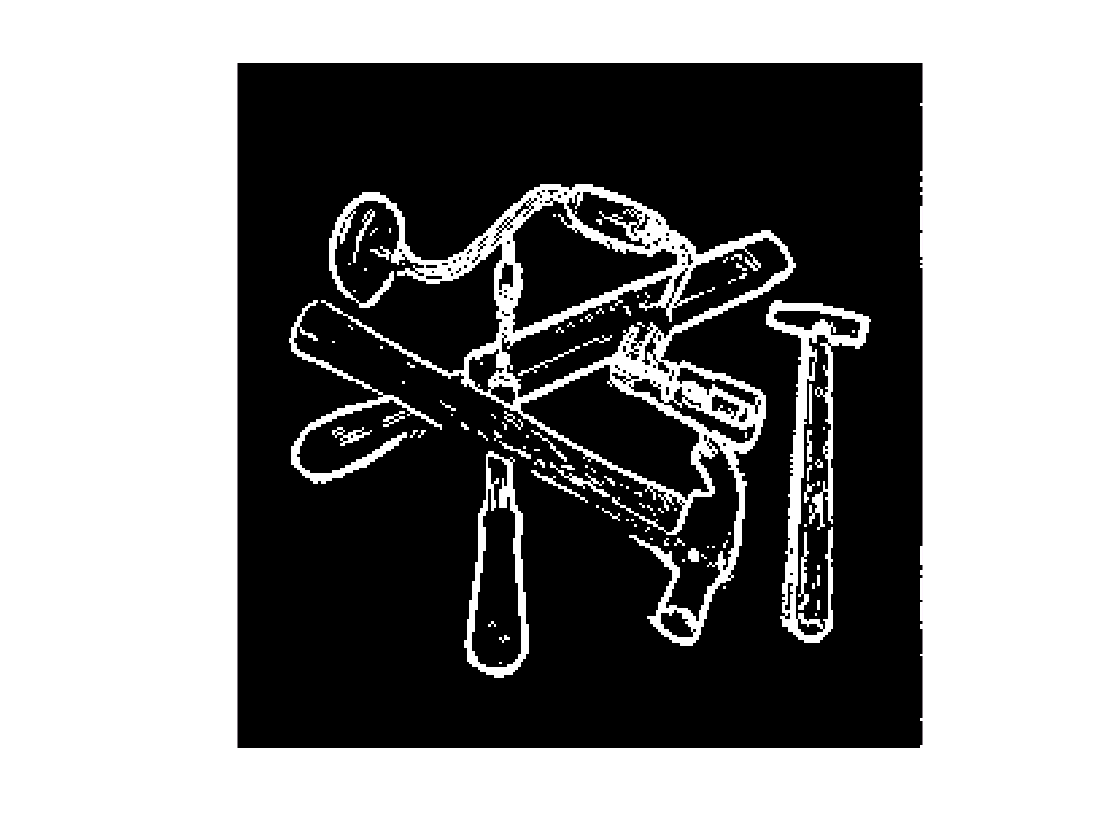

threshold = 15;
showgrey((gradmagntools-threshold)>0);

Perform the same study on the image **godthem256.**

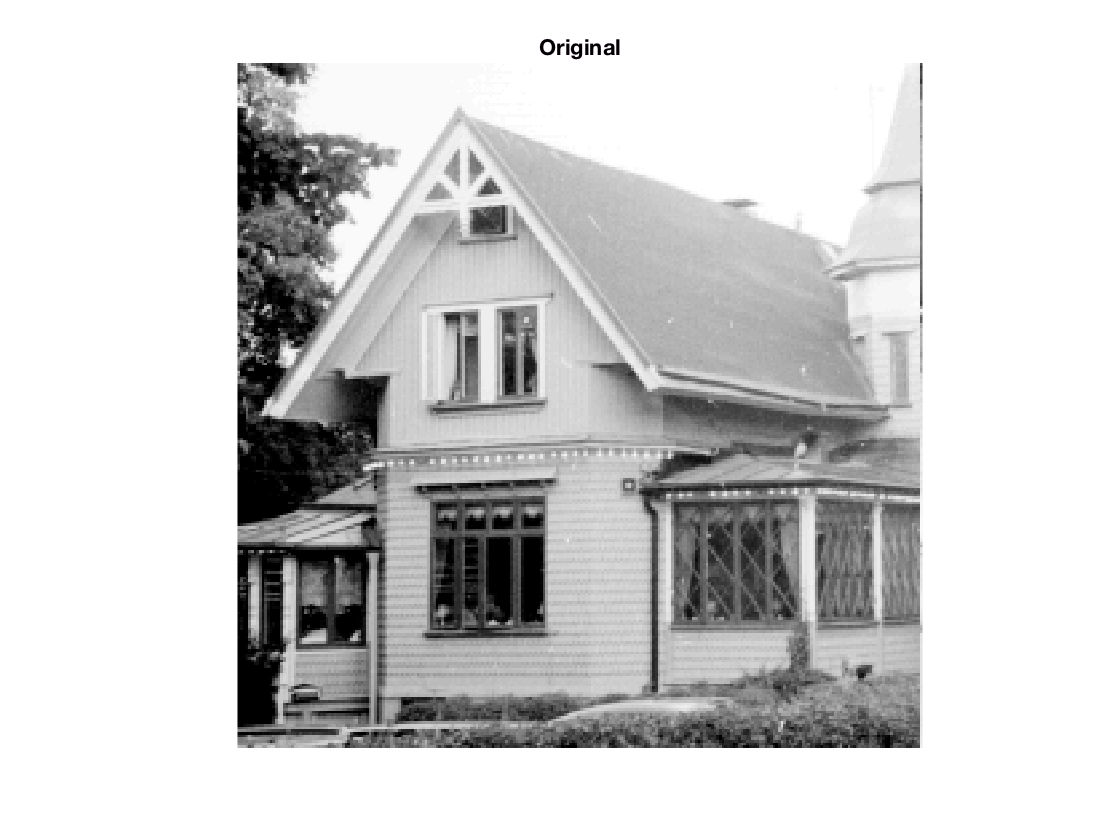

pic = godthem256;
showgrey(pic);

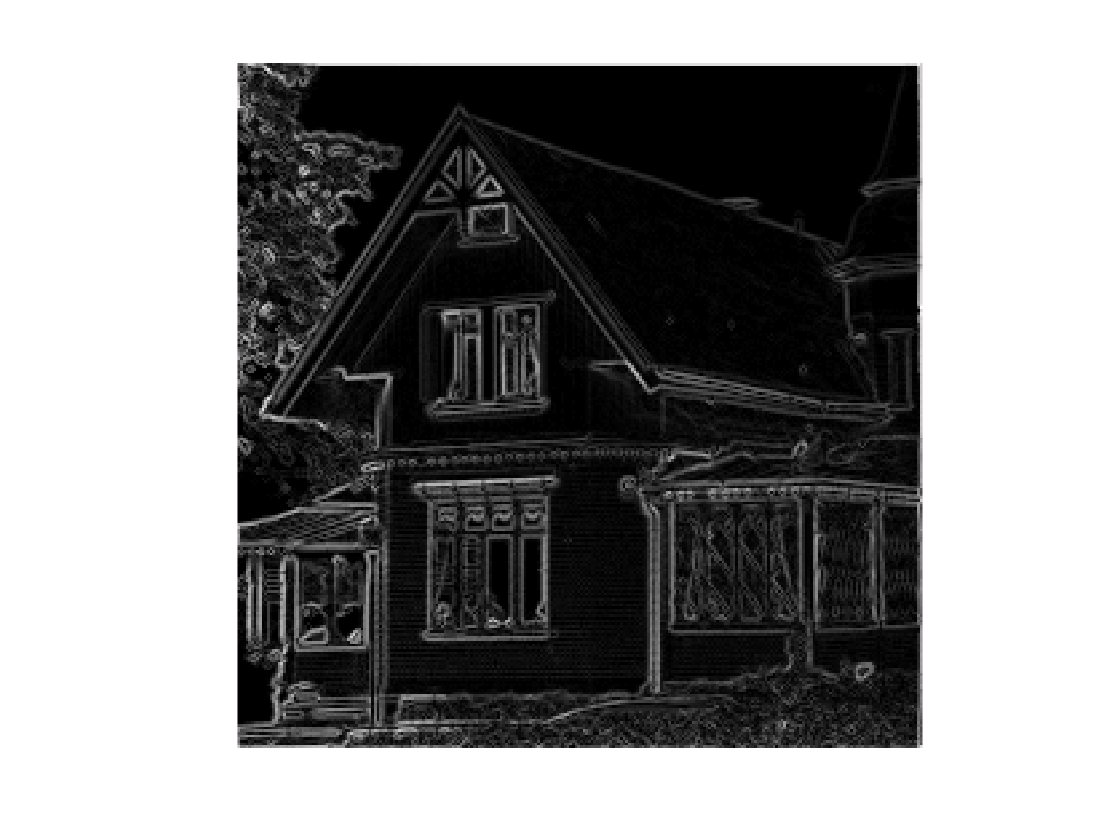

gradmagpic = sqrt(Lv(pic));
showgrey(gradmagpic);

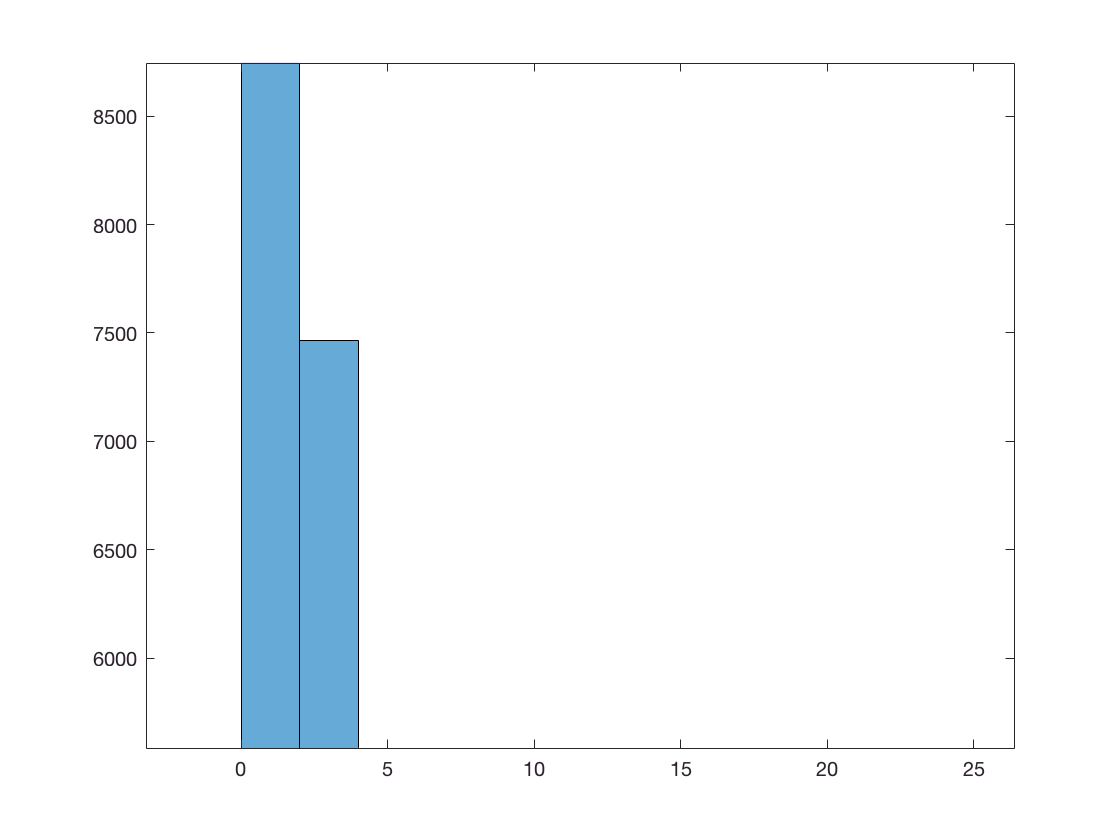

histogram(gradmagpic);

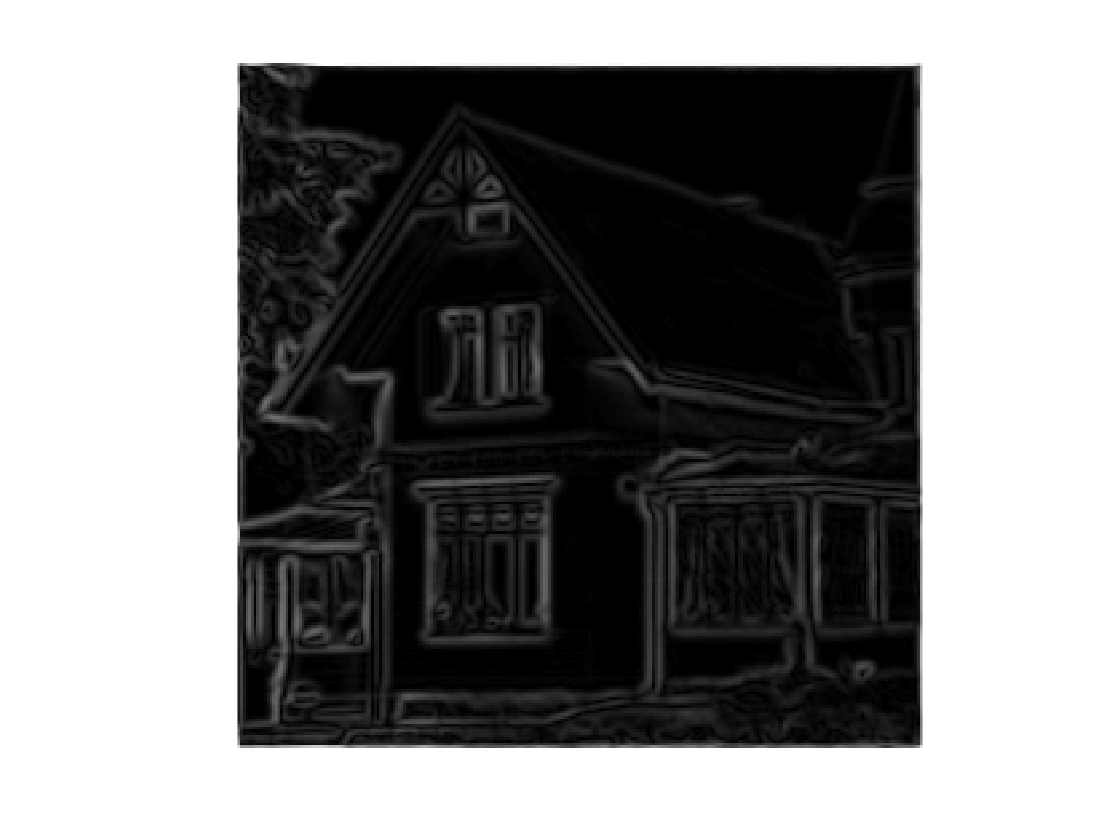

t = 2 ; 
gpic = discgaussfft(pic, t);
gradmaggpic = sqrt(Lv(gpic));
showgrey(gradmaggpic);

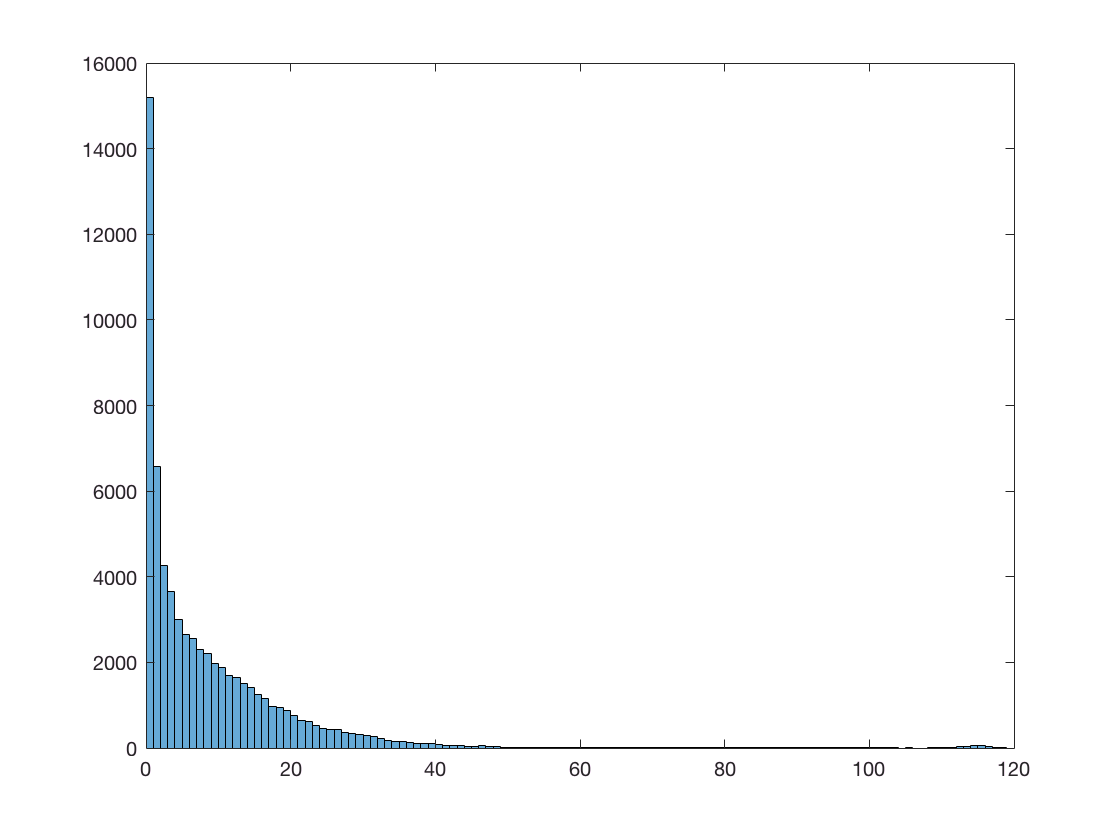

histogram(gradmaggpic(:));

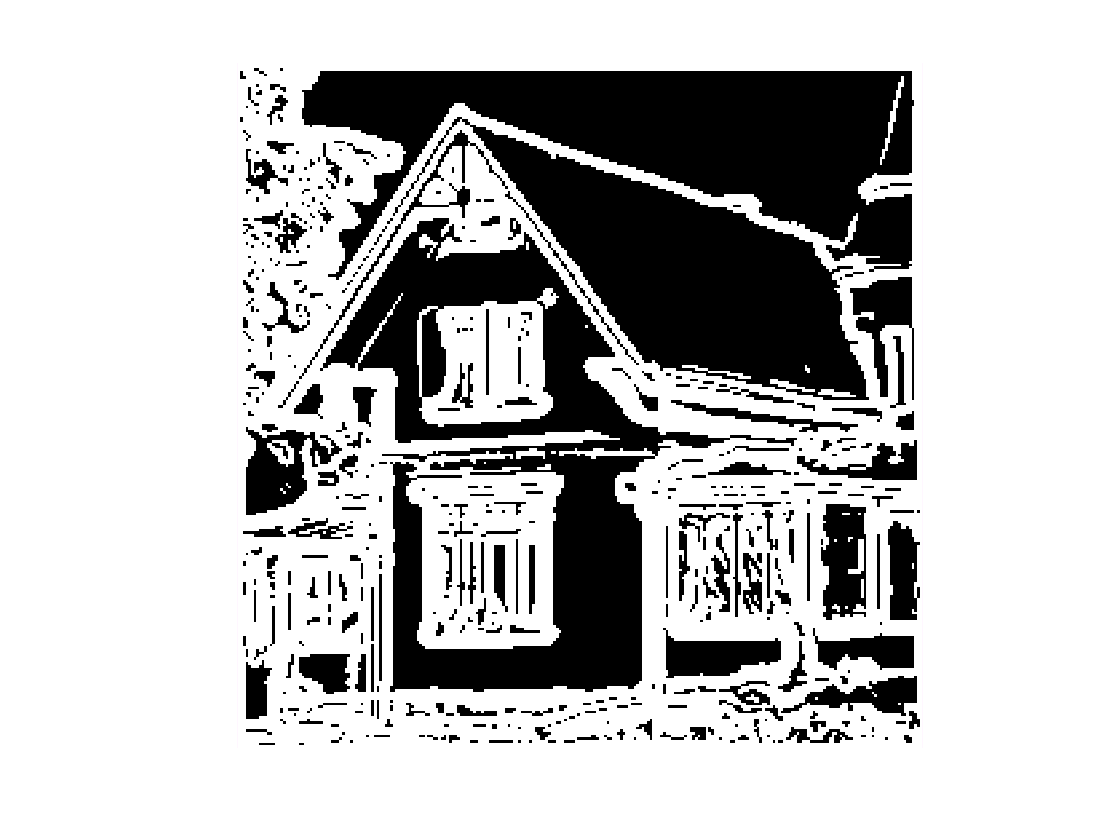

threshold = 5;
showgrey((gradmaggpic-threshold)>0);

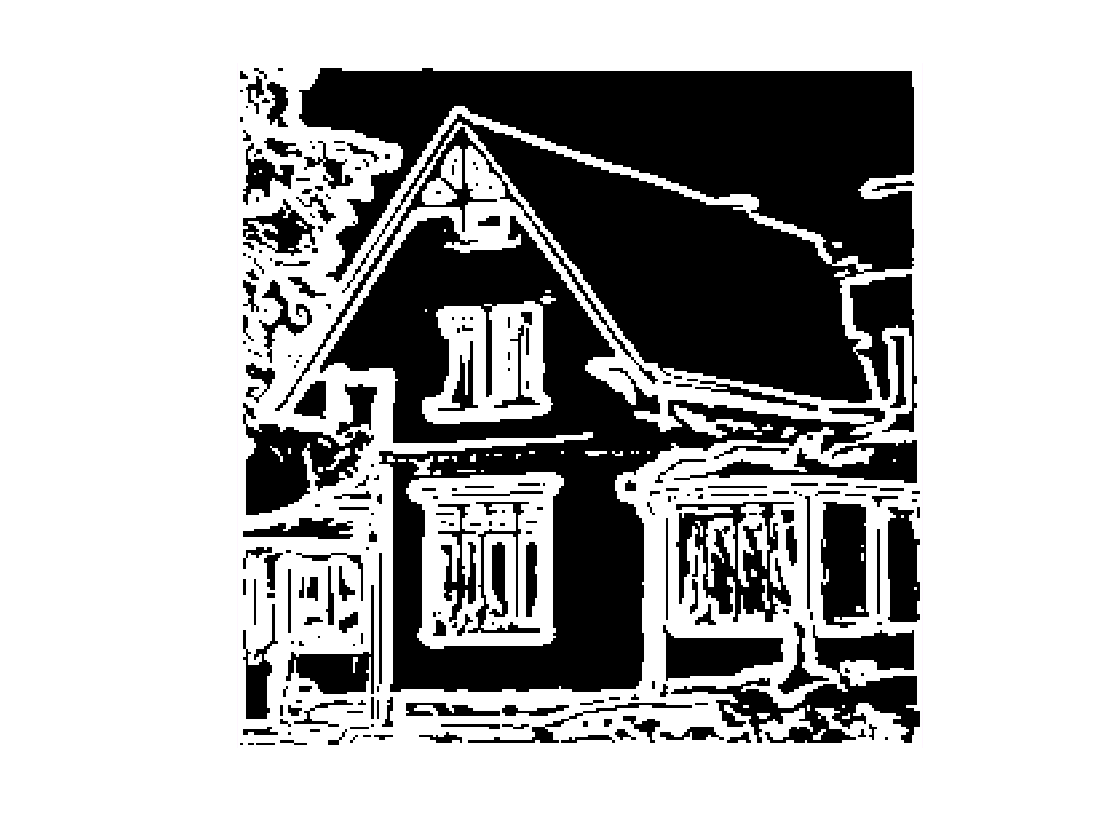

threshold = 7.5;
showgrey((gradmaggpic-threshold)>0);

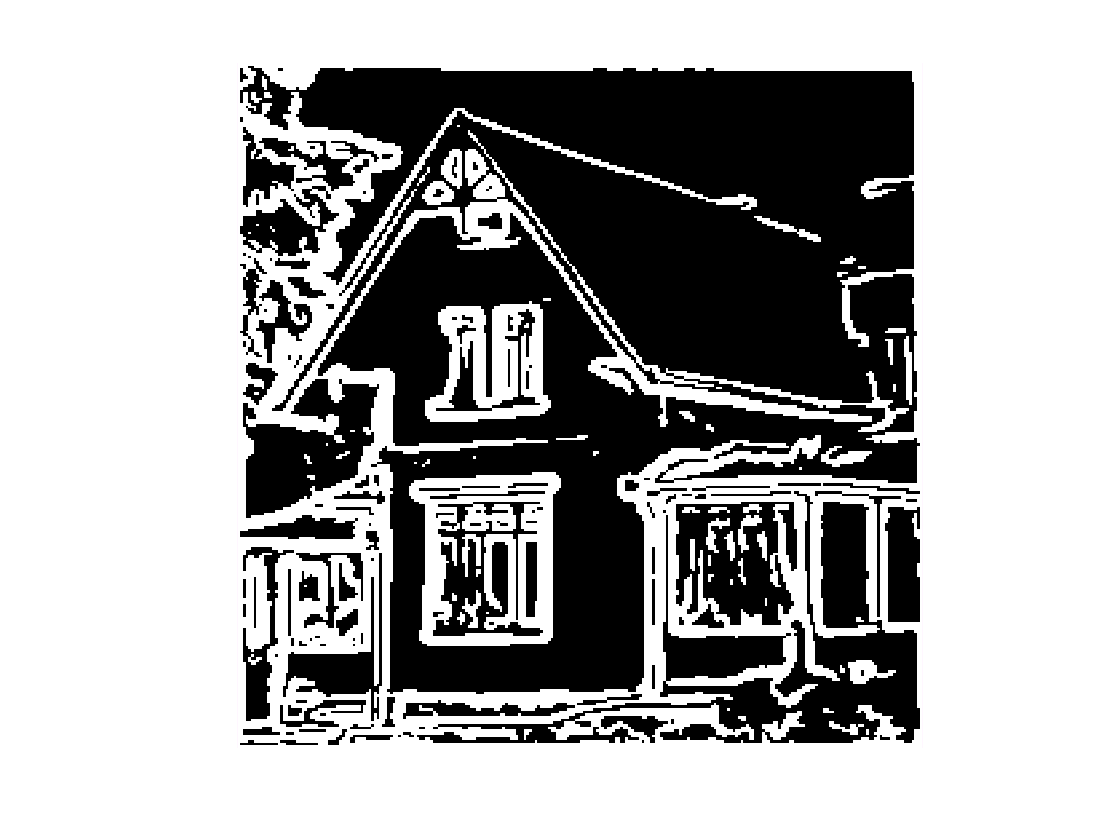

threshold = 10;
showgrey((gradmaggpic-threshold)>0);

## 3 Differential geometry based edge detection: Theory

Question 4 to 6

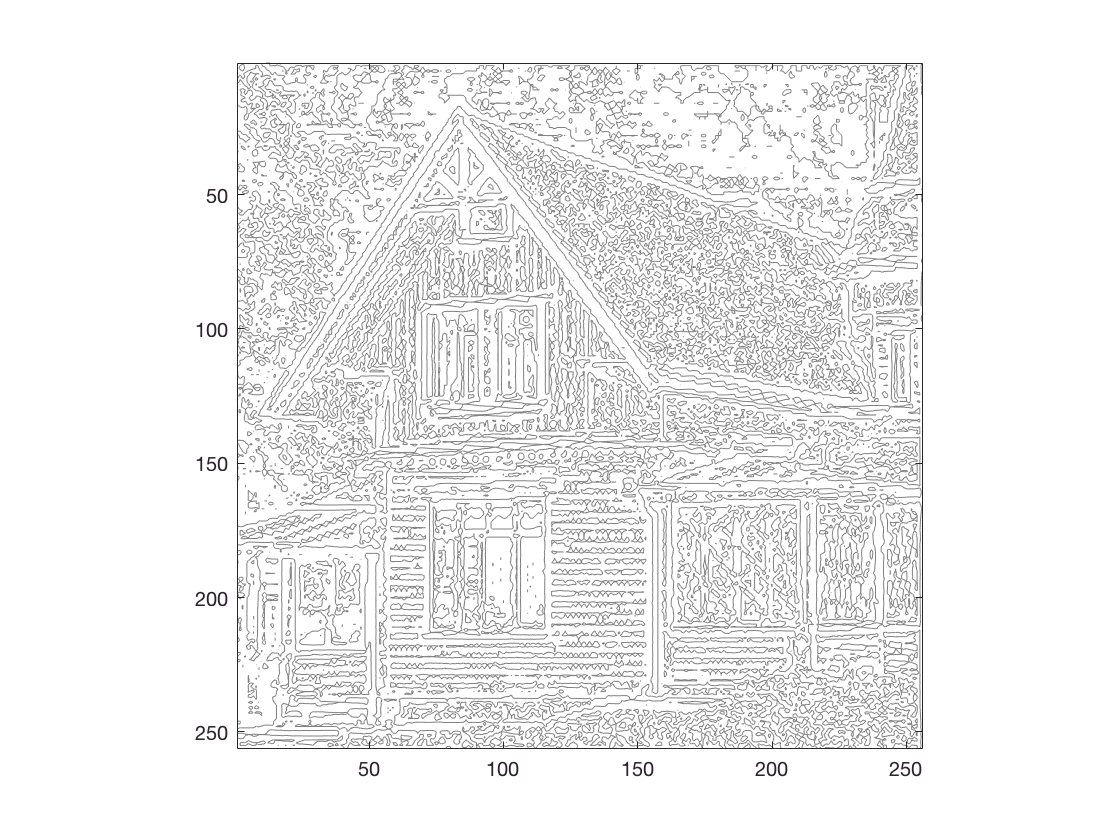

scale = [0.0001 1.0 4.0 16.0 64.0];
house = godthem256;gitex
contour(Lvvtilde(discgaussfft(house,scale(1)), 'same'), [0 0])
axis('image')
axis('ij')

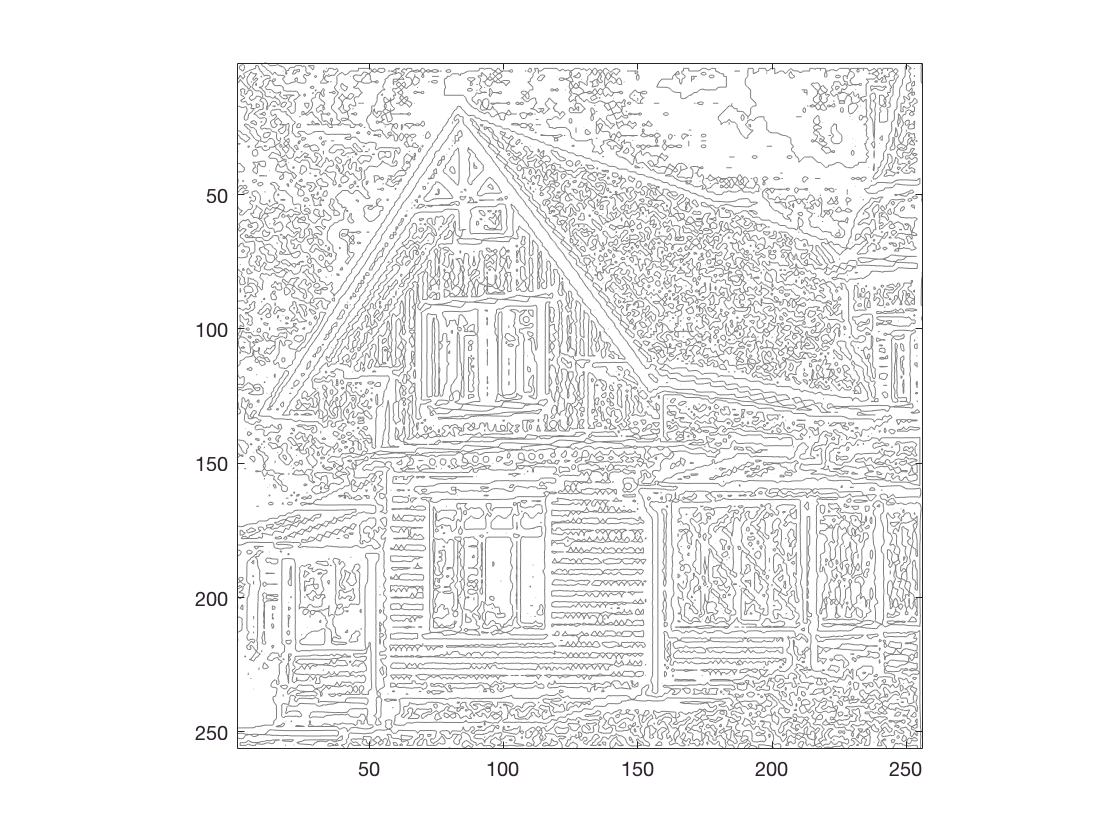

contour(Lvvtilde(discgaussfft(house,scale(2)), 'same'), [0 0])
axis('image')
axis('ij')

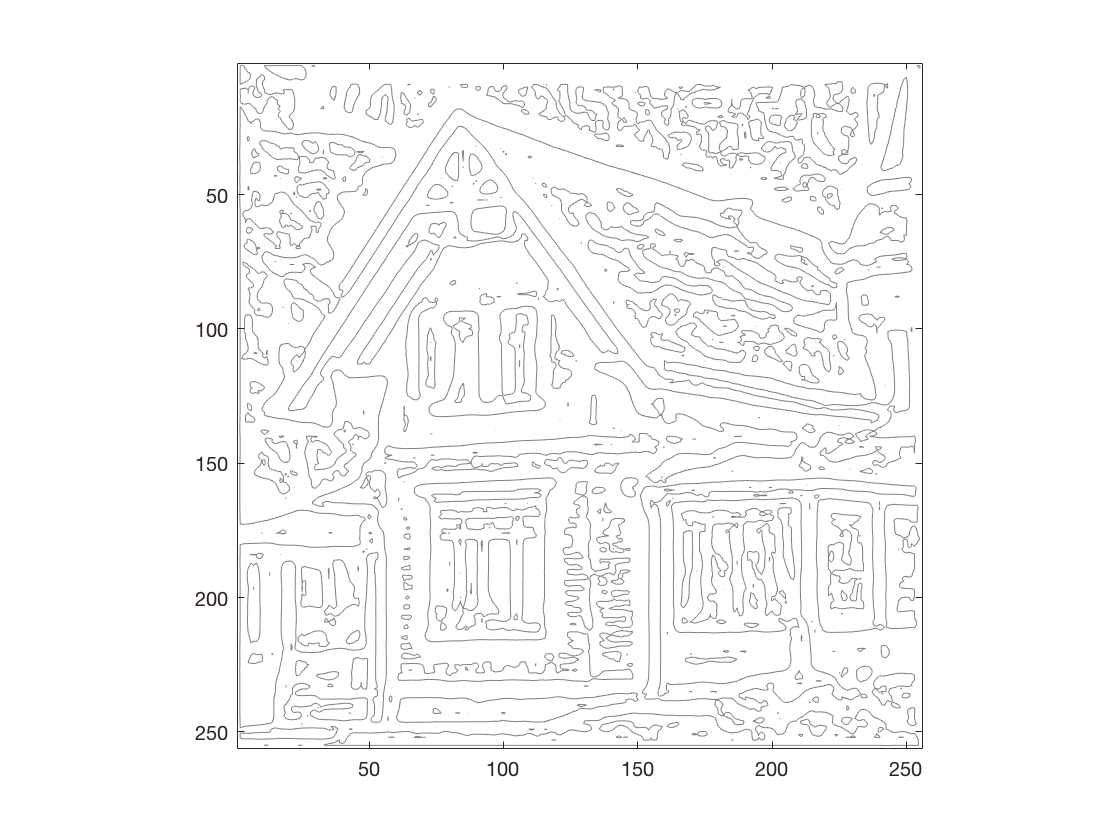

contour(Lvvtilde(discgaussfft(house,scale(3)), 'same'), [0 0])
axis('image')
axis('ij')

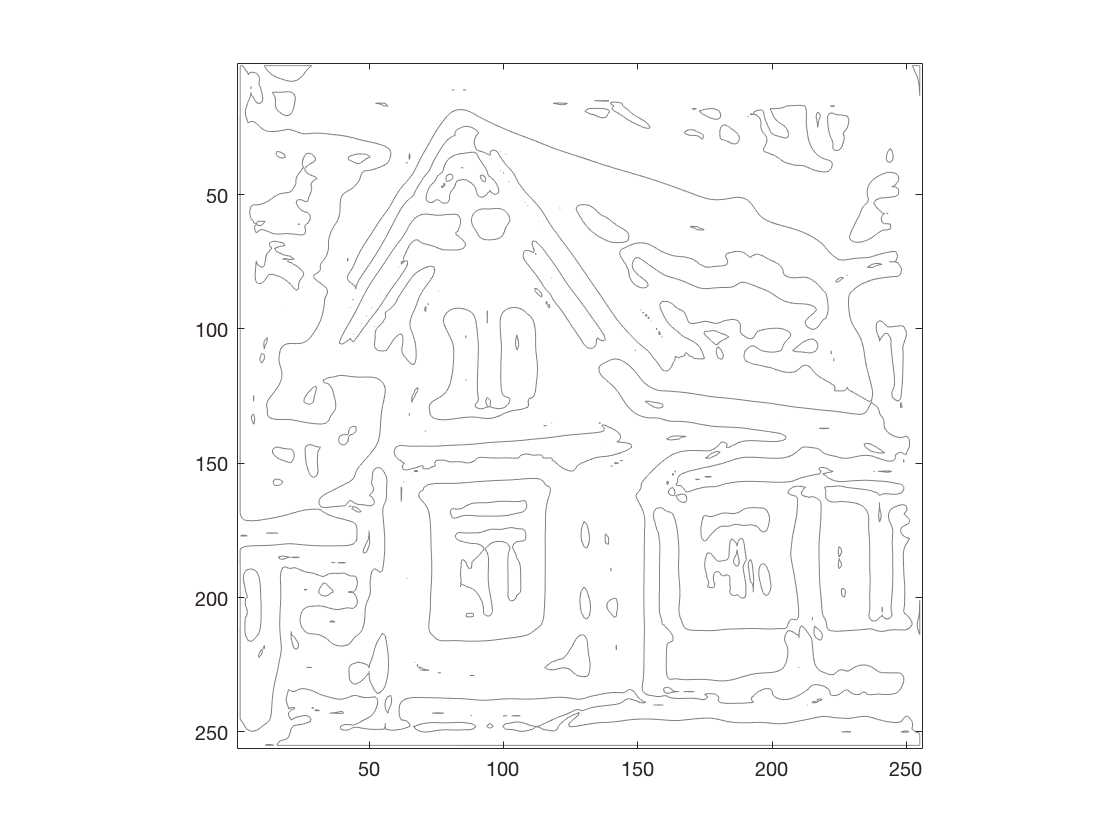

contour(Lvvtilde(discgaussfft(house,scale(4)), 'same'), [0 0])
axis('image')
axis('ij')

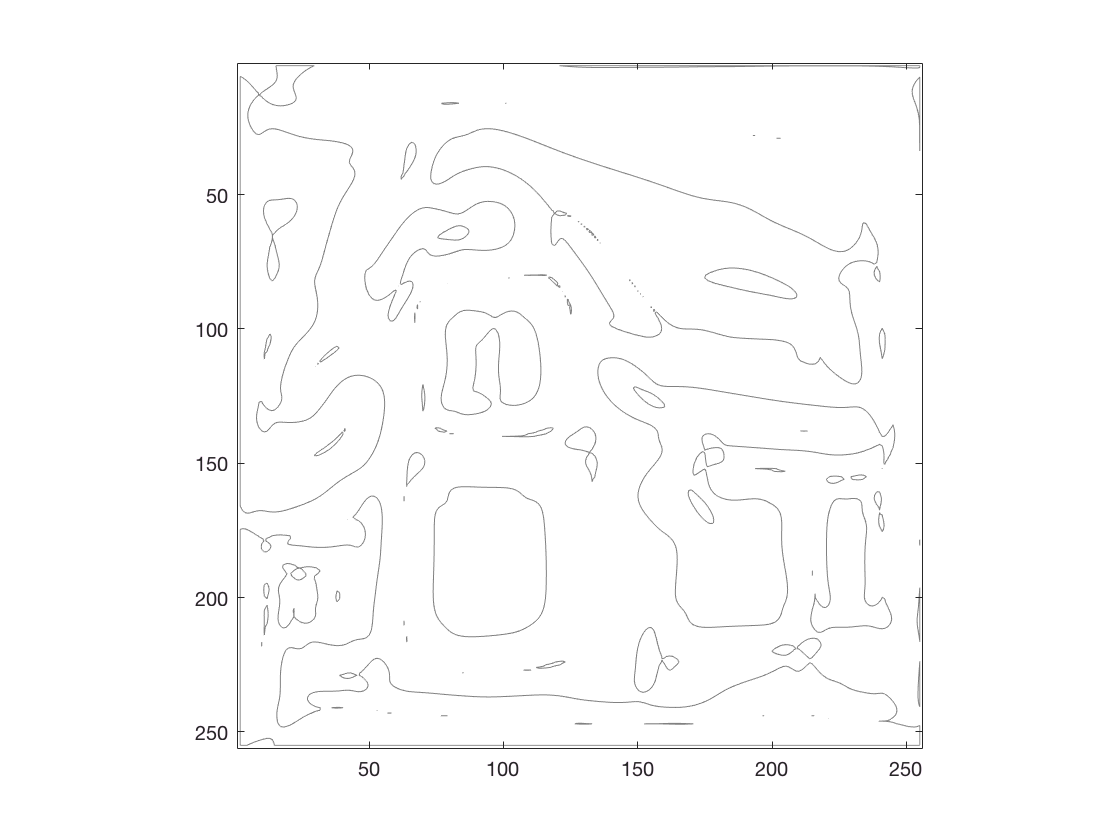

contour(Lvvtilde(discgaussfft(house,scale(5)), 'same'), [0 0])
axis('image')
axis('ij')